# ASSIGNMENT 1

Gianpaolo Mastroiacovo ()

Antonio Di Giovanni (03743324)

Data(?)

## Exercise 1.1)

#### MATRIX CREATION

A = [1 3 5; 4 3 -1; 6 -2 9]

A =      1     3     5
     4     3    -1
     6    -2     9



B = [1 2 4; 11 3 8; 9 5 2]

B =      1     2     4
    11     3     8
     9     5     2


#### *A)*

A(2,1)

ans = 4

#### *B)*

A(1,:)

ans =      1     3     5


#### *C)*

A(:,3)

ans =      5
    -1
     9


#### *D)*

sum(A,2)

ans =      9
     6
    13


#### *E)* 

prod(A,1)

ans =     24   -18   -45


#### *F)*

mean(A,1)

ans =     3.6667    1.3333    4.3333


#### *G)*

A(A<2)

ans =      1
    -2
    -1


#### *H)*

B(B>4 & B<9)

ans =      5
     8


#### *I)*

A(A<0) = 0

A =      1     3     5
     4     3     0
     6     0     9


sum(A,"all")

ans = 31

Bringing the Matrix to its original value (with negative numbers)

A = [1 3 5; 4 3 -1; 6 -2 9];

#### *J)*

mean(A(:,[1,3]),"all")

ans = 4

#### *K)*

transpose (A)

ans =      1     4     6
     3     3    -2
     5    -1     9


#### *L)*

trace (A)

ans = 13

#### *M)*

A * B

ans =     79    36    38
    28    12    38
    65    51    26


#### *N)*

A .* B 

ans =      1     6    20
    44     9    -8
    54   -10    18


## Exercise 1.2)

save("A","A");
save("B","B");

clear;

load("A.mat","A");
load("B.mat","B");

## Exercise 1.3)

The code for this exercise has been moved at the end of the document, as it requires to define a function.

## Exercise 1.4)

The code for this exercise has been moved at the end of the document, as it requires to define a function.

## Exercise 1.5)

V = []; %how to pre-define the dimension of this vector?
for i = 1:100
    if rem(i,2) == 0
        V = [V, i];
    elseif rem(i,3) == 0        
        V = [V,i];
    end
end

mean(V)

ans = 51

sum(V)

ans = 3417

## Exercise 1.6)

a = 10;
b = 10;
C = a.*randn(100,1) + b;

#### *A)*

meanC = mean(C)

meanC = 11.2309

stdC = std(C)

stdC = 11.6240

#### *B)*

if meanC > a
    fprintf("The calculated mean (%.2f) is above %d\n", meanC, b)
elseif meanC == a
    fprintf("The calculated mean (%.2f) is equal to %d\n", meanC, b)
else
    fprintf("The calculated mean (%.2f) is below %d\n", meanC, b)
end

The calculated mean (11.23) is above 10


#### *C)*

N = 10^6;
a = 10;
b = 10;
meanR = zeros(N,1);
minR = zeros(N,1);
maxR = zeros(N,1);
stdR = zeros(N,1);

for i = 1:N
    R = a .* randn(100,1) + b;
    meanR(i) = mean(R);
    minR(i) = min(R);
    maxR(i) = max(R);
    stdR(i) = std(R);
end

% Check if MATLAB starts indexing with 0 or 1

#### *D)*

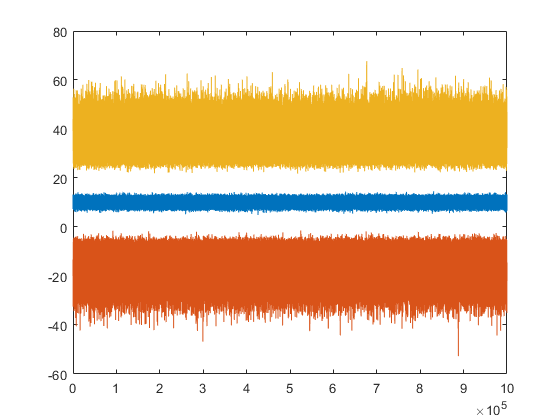

plot(1:N,meanR,1:N,minR,1:N,maxR)

## Exercise 1.7)

BirthDay = datetime(1998,07,21);
Now = datetime("now", "Format","dd-MMM-yyyy");
Years = split(between(BirthDay, Now,"years"),"years");
BirthDays = BirthDay + calmonths(12:12:Years*12);

#### *A)*

A = dateshift(BirthDays, "dayofweek", "Sunday")

A = 1×22 datetime array
   25-Jul-1999   23-Jul-2000   22-Jul-2001   21-Jul-2002   27-Jul-2003   25-Jul-2004   24-Jul-2005   23-Jul-2006   22-Jul-2007   27-Jul-2008   26-Jul-2009   25-Jul-2010   24-Jul-2011   22-Jul-2012   21-Jul-2013   27-Jul-2014   26-Jul-2015   24-Jul-2016   23-Jul-2017   22-Jul-2018   21-Jul-2019   26-Jul-2020


#### *B)*

[Dnum, Day] = weekday(BirthDays, "long");
isSunday = strcmp(Day,"Sunday");
A (isSunday == 1)

ans = 1×3 datetime array
   21-Jul-2002   21-Jul-2013   21-Jul-2019


#### *C)*

between(Now,(BirthDays(end) + calmonths(12)))

ans = calendarDuration
   3mo 1d 14h 11m 53.665s


## Exercise 1.8)

#### *A)*

V = binvar(3,1);

#### *B)*

Z = intvar(3,4);

#### *C)*

K = diag(sdpvar(5,1),0);

## Exercise 1.9) 

C = [-1; -1/3];
A = [1 1; 4 1/4; 1 -1; -1/4 -1; -1 -1; -1 1];
b = [2; 1; 2; 1; -1; 2];
X = sdpvar(2,1);

cons = A * X <= b;
obj = transpose(C) * X;
ops = sdpsettings('solver','gurobi','verbose',0);

S = optimize(cons,-obj,ops);

## Exercise 1.3)

function [Min,Max] = MatrixBounds(A)
Max = max(A(:));
Min = min(A(:));
end

## Exercise 1.4)

function [out] = Factorial(in)

x = in - 1;

while x > 1
in = in * x;
x = x - 1;
end

out = in;
end